In this example we compare MINRES and CG on some pseudorandom SPD problems. The first matrix has a condition number of 100. 

n = 1000;
density = 0.008;
A = sprandsym(n,density,1e-2,2);

We cook up a linear system whose solution we happen to know exactly.

x = (1:n)'/n;
b = A*x;

Now we apply both methods and compare the convergence of the system residuals, using the built-in function `pcg` in the latter case.

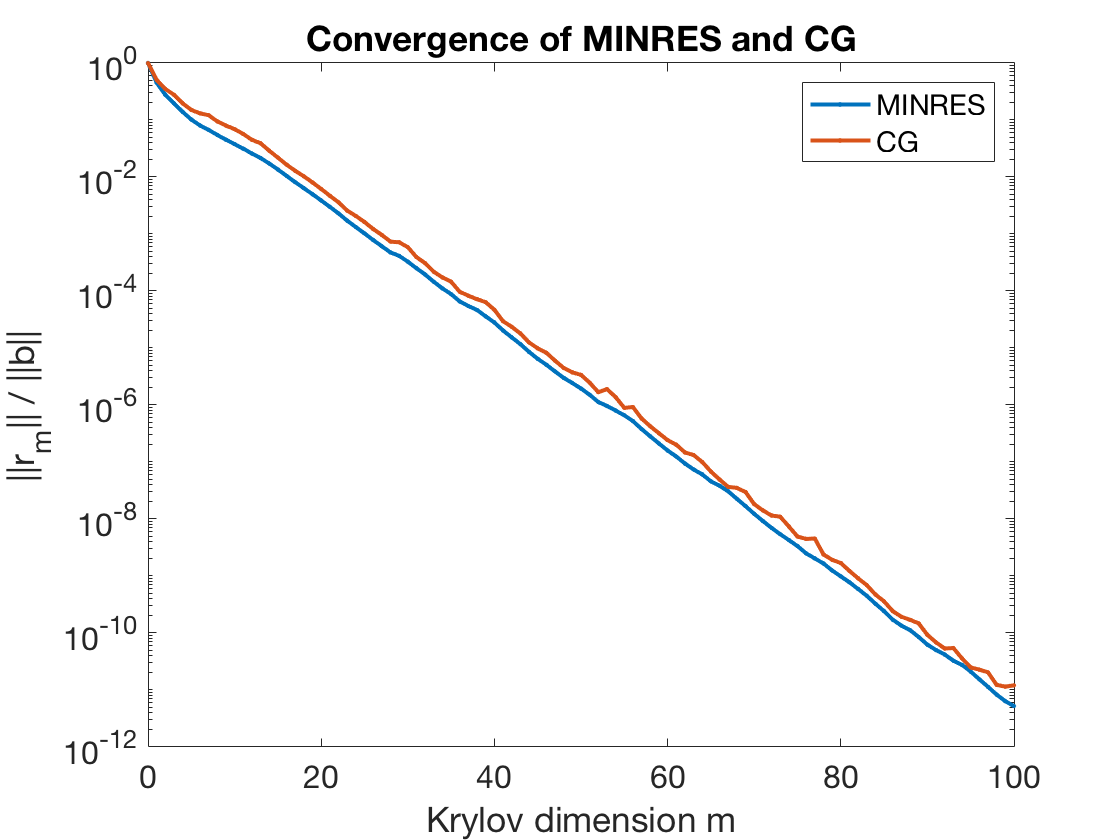

[xMR,~,~,~,residMR] = minres(A,b,1e-12,100);
[xCG,~,~,~,residCG] = pcg(A,b,1e-12,100);
semilogy(0:100,residMR/norm(b),'.-')
hold on, semilogy(0:100,residCG/norm(b),'.-')
title('Convergence of MINRES and CG') % ignore this line
xlabel('Krylov dimension m'), ylabel('||r_m|| / ||b||')     % ignore this line
legend('MINRES','CG')   % ignore this line

There is virtually no difference between the two methods here when measuring the residual. We see little difference in the errors as well. 

errorMR = norm( xMR - x ) / norm(x)

errorMR =      4.172154993984259e-11


errorCG = norm( xCG - x) / norm(x)

errorCG =      3.417147437089948e-11


Next we use a system matrix whose condition number is $10^4$. 

A = sprandsym(n,density,1e-4,2);

Now we find that the CG residual jumps up initially, and then both methods converge at about the same linear rate. Note that both methods have actually made very little progress after 100 iterations, though. 

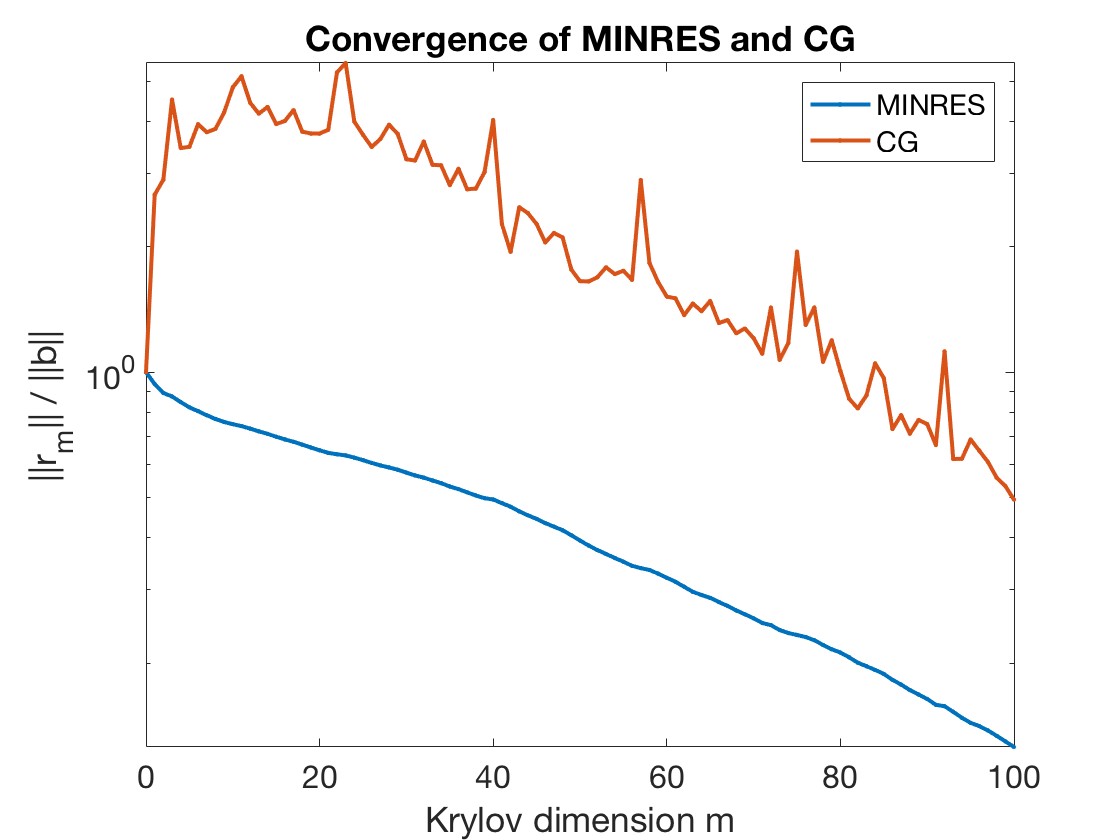

[xMR,~,~,~,residMR] = minres(A,b,1e-12,100);
[xCG,~,~,~,residCG] = pcg(A,b,1e-12,100);
clf
semilogy(0:100,residMR/norm(b),'.-')
hold on, semilogy(0:100,residCG/norm(b),'.-')
title('Convergence of MINRES and CG') % ignore this line
xlabel('Krylov dimension m'), ylabel('||r_m|| / ||b||')     % ignore this line
legend('MINRES','CG')   % ignore this line

The errors confirm that we are nowhere near the correct solution in either case.

errorMR = norm( xMR - x ) / norm(x)

errorMR =      8.781224105035702e+02


errorCG = norm( xCG - x) / norm(x)

errorCG =      9.594571597572971e+02
